17.59

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
a = 0.31;
tau = 0.029;
k = 14.3;
Ts = 0.01;
wc = 2 * pi * 5;
dc = 1 / sqrt(2);
umax = 10;
bit = 10;
res = 2000;

rad2deg = 180 / pi;
deg2rad = pi / 180;
deg2pulse = res / 360;
pulse2deg = 360 / res;
rad2pulse = rad2deg * deg2pulse;
pulse2rad = pulse2deg * deg2rad;

s = tf("s");
Pc = mot.k / (s * (mot.T * s + 1));
[numPc, denPc] = tfdata(Pc, 'v');
Pd = c2d(Pc, Ts, "zoh");
[numPd, denPd] = tfdata(Pd, 'v');
z = tf("z", Ts);
s = (z - 1) / Ts;
Cd = minreal(k * (1 + tau * s) / (1 + a * tau * s), 1e-6);
[numCd, denCd] = tfdata(Cd, 'v');
Qd = minreal(wc^2 / (s^2 + 2 * dc * wc * s + wc^2), 1e-6);
[numQd, denQd] = tfdata(Qd, 'v');
QdPd = minreal(Qd / Pd, 1e-6);
[numQdPd, denQdPd] = tfdata(QdPd, 'v');

r.A = 50; % [deg]
r.t = 0; % [s]
d.A = 5; % [V]
d.t = 1; % [s]

open_system("ex3_sim1m.slx")

set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "2")
sim("ex3_sim1m")

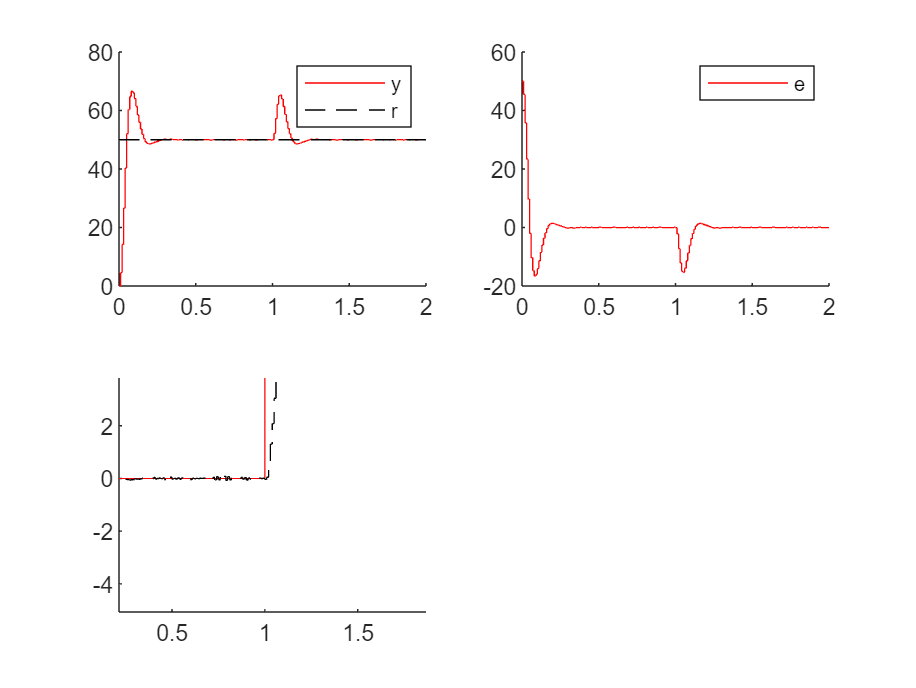

close all
figure(1)
subplot(2, 2, 1)
hold on
stairs(sim1_res.time, sim1_res.signals(1).values, "r")
stairs(sim1_res.time, sim1_res.signals(2).values, "k--")
legend("y", "r")

subplot(2, 2, 2)
hold on
stairs(sim1_res.time, sim1_res.signals(3).values, "r")
legend("e")

subplot(2, 2, 3)
hold on
plot(sim1_res.time, sim1_res.signals(4).values, "r")
stairs(sim1_res.time, sim1_res.signals(5).values, "k--")
legend("real", "measured")

Nonostante il controllore sia privo di un polo nell'origine, il sistema riesce a reiettare perfettamente i disturbi di carico costante.

18.36